path_root
load([path_root '\results\ew_6-hr_20iterations_gridsearch\results.mat'])

nnc0 = nnc(ii);
nnd0 = nnd(ii);
lead = nnc0.model([nnc0.model.io] == 0).shift;

[~,t,~,ys,nets,trs] = unpack_data(nnd0,'type','array');
y = mean(ys,2);
event_prom = .6; 
event_threshold = 60; 
event_sw = [lead/2 lead];

[tIds,yIds] = get_events(t,y,...
    event_prom,event_threshold,event_sw);

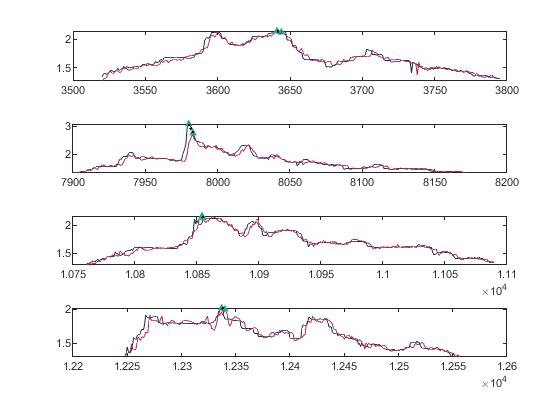

pdt =     -3
    -3
     1
    -3


pda =     0.0217
    0.3204
   -0.0358
    0.0180



%calculate peak error
[pdt,pda] = perf_pd(t,y,tIds,yIds,'plt',true)

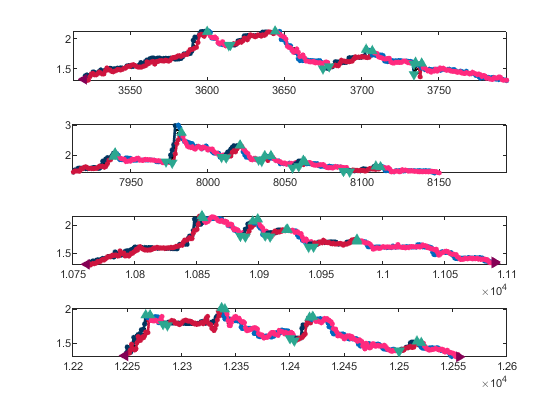

sdt =    -1.6471
   -1.8400
   -1.6471
   -2.7059


sda =     0.0011
    0.0291
   -0.0011
    0.0102



%calculate series distance error
sd_minor_prom = 0.1;
sd_sw = event_sw;
[sdt,sda,~,~] = perf_sd(t,y,tIds,yIds,sd_sw,sd_minor_prom,'plt',true)

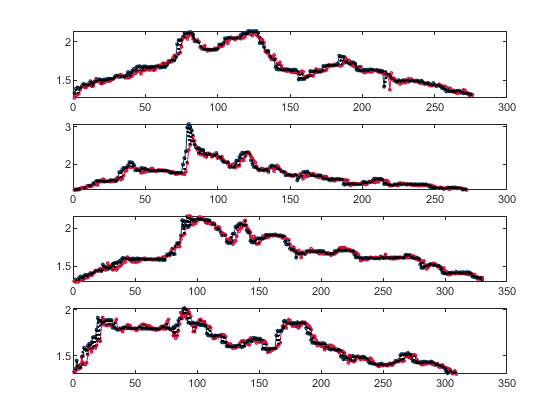

hmt =    -1.5543   -1.5074   -1.3212   -1.5631


hma =     0.0085    0.0208    0.0025    0.0063



hm_b = 0.001;
hm_sw = event_sw;
[hmt,hma] = perf_hm(t,y,tIds,yIds,hm_sw,hm_b,'plt',true)

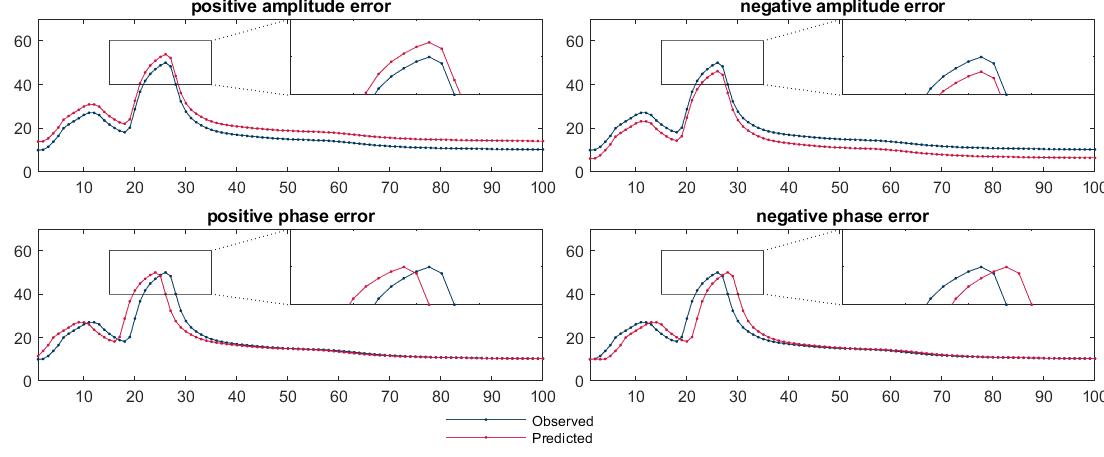

explain_nse;